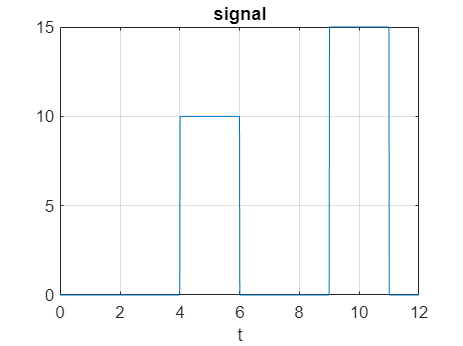

% Exercice 10
clear all;
close all;

% a)
fe = 100;
te = 1/fe;
t = 0:te:12;

% b)
s1 = zeros(1,4*fe+1);
s2 = 10*ones(1,2*fe);
s3 = zeros(1, 3*fe);
s4 = 15*ones(1,2*fe);
s5 = zeros(1,fe);

s = [s1 s2 s3 s4 s5];

figure;
plot(t, s);
grid;
title('signal');
xlabel('t');


% Avant correction 
b = randn(size(s));
var(b);

ans = 0.9225

std(b);

ans = 0.9604

mean(b);

ans = -0.0206

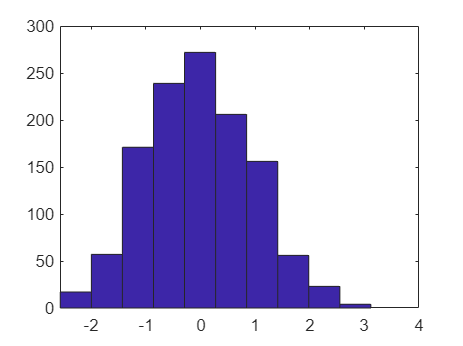

hist(b);


% Après correction
b = b-mean(b); % moyenne nulle
b = b/std(b); % var = 1
var(b);

ans = 1.0000

std(b);

ans = 1

mean(b);

ans = 0

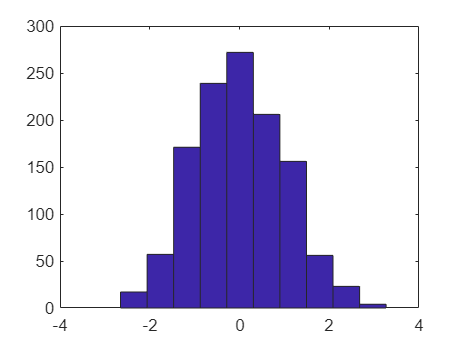

hist(b);

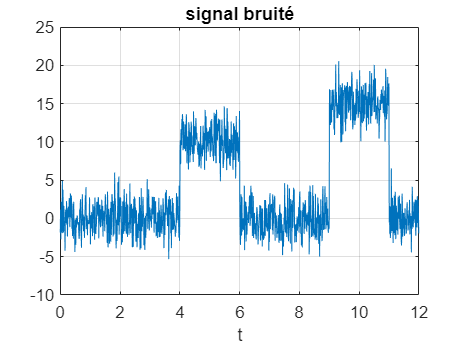


b = b*2; % ecart-type = 2

sb = s+b;
figure;
plot(t, sb);
grid;
title('signal bruité');
xlabel('t');

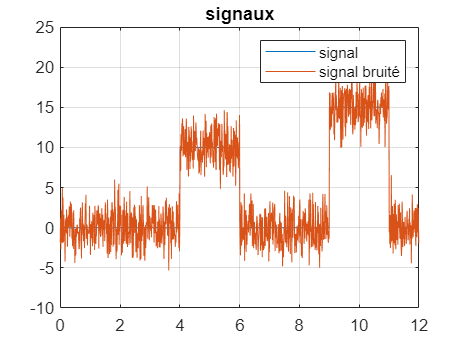


figure;
plot(t, s);
hold on;
plot(t ,sb);
grid;
title('signaux');
legend('signal','signal bruité');